## Alpha3 filters

The Alpha3 provides two filters in series:

- A resonant low-pass filter with adjustable steepness

- A high-pass filter

### Low-pass filter

#### Steepness

The steepness defines the shape of the cut-off: with low values, the filter smoothly cuts the frequencies.

Let $s\in \left\lbrack 0,120\right\rbrack$ be the steepness parameter, the corresponding ratio is $\rho_s =\frac{s}{120}$. The number of decibels per octave is computed as follows:


$${\textrm{db}}_{\textrm{octave}} \left(\rho_s \right)=m+\left(M-m\right)\;\rho_s$$


Where:

- $m$ is the minimum number of decibels per octave, equal to 6

- $M$is such that the filter is 2-poles when $s=30$ and 4-poles when $s=90$

- As a consequence, for $s=120$ and below, the steepness is 30 decibels per octave, which makes it pretty aggressive

#### Cutoff frequency

The filter is designed to have a cutoff frequency $F_c \in \left\lbrack 10,20000\right\rbrack$. The rationale for having a minimum value lower than 20Hz is the balance with the steepness.

For perceptive reason, the parameter defining $F_c$ is not linear, but rather logarithmic, with the possiblity to fine tune in the most common frequencies (something between 200 and 2000Hz).

A possible design is to compute $F_c$ using three tunable segments:

- Grow fast in the frequency range [0,200]

- Grow slowly in the range [200, 2000]

- Grow fast beyong 2000Hz

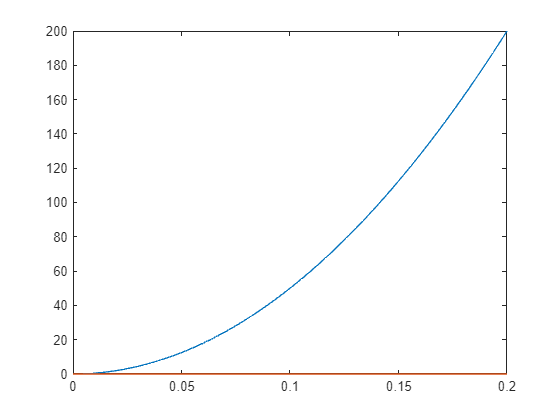

function y = get_freq(x)
    a = 200;
    b = 1800;
    c = 20000;
    if (x < 0.2)
        y = a * power(x / 0.2, 2);
    elseif (x < 0.8)
        y = a + b * log(1 + (x - 0.2) / 0.35);
    else
        y = a + b + (c - a - b) * power((x - 0.8) / 0.2, 2);
    end
end
function plot_range(xmin, xmax)
    c = linspace(xmin, xmax, 128);
    fc = zeros(128);
    for i = 1:128
        x = c(i);
        fc(i) = get_freq(x);
    end
    ymin = min(fc, [], "all");
    ymax = max(fc, [], "all");

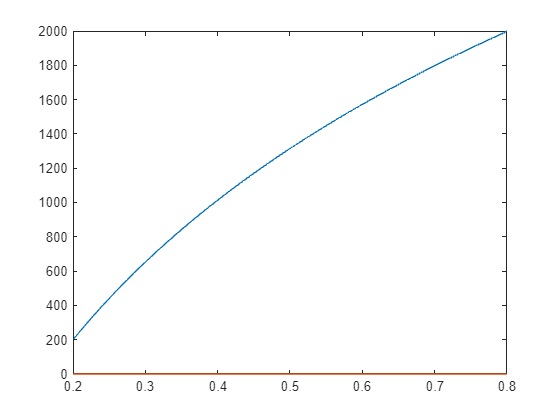

    plot(c, fc);

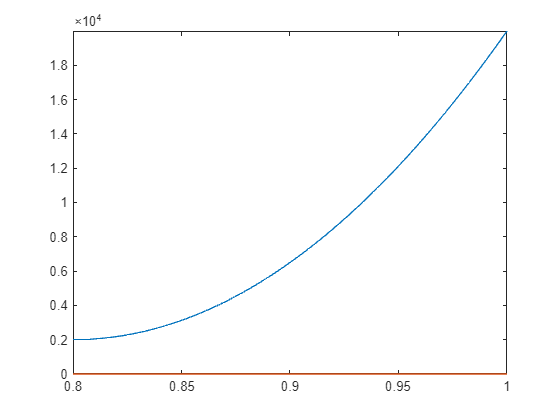

    xlim([xmin, xmax]);

    ylim([ymin ymax]);
end
plot_range(0, 0.2);
plot_range(0.2, 0.8);
plot_range(0.8, 1);

#### Resonance

TODO

### High-pass filter

TODO